# 7A_fractured sample analysis

clearvars;
% navigate to the correct directory 
if exist('goto','file')
    goto(3); % this is my way of going to the project file
end

sevenAFracturedImageFileName = '7A_fractured_image.mat';
sevenAFracturedImageFilePath = fullfile('runs','7A_fractured','20220301',sevenAFracturedImageFileName);

% loading the data
dataWasNotSaved = false; % this assumes data was already saved previously
if dataWasNotSaved
    data = loadImageSeq(fullfile('..','..','data','Bland','7A_fractured','8bitJPG'),'jpg');
    save(sevenAFracturedImageFilePath,'data','-v7.3','-mat');
else
    load(sevenAFracturedImageFilePath);
end

Inspecting the 820 slice

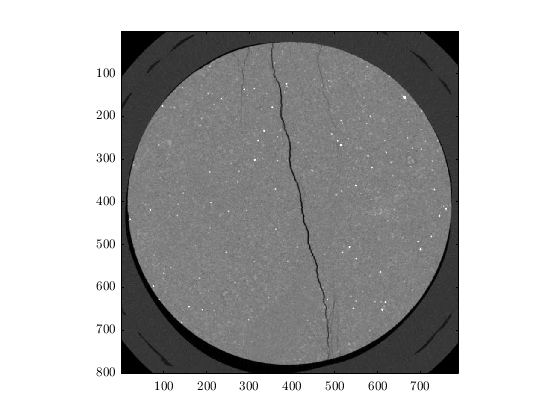

figure
imagesc(data.image(:,:,820));
colormap('gray');
axis image
ax = gca;
ax.CLim = [10 75];

% run the following line in the command window
%volumeViewer(data.image)

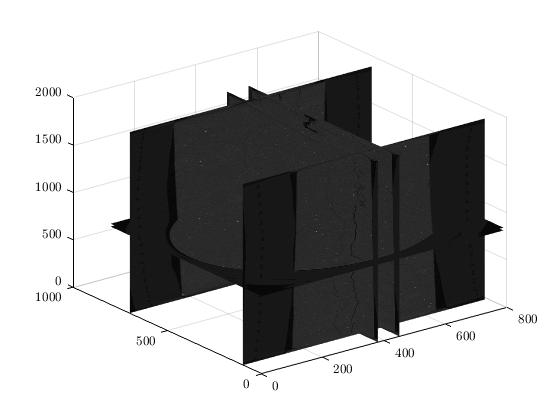

slice(data.image,[380 450],[100 700],[820 850])
shading interp

axis image

% relevant functions
help subvolume